% Setting up parameters of Monte Carlo simulation
% ---------------------------------------
clc
clear all
clf

numMonteCLoops = 1E4; % Number of Monte Carlo Loops
N = 1; % Number of observations
noise_var = 2; % Variance of WGN
theta = 10; % True value of the parameter
% ---------------------------------------

% Initializing variable for stability
estimate = ones(1,numMonteCLoops)*NaN;

for MC=1:numMonteCLoops
    %%% defining the Numerator in the estimator equation
    % x[n]*n = theta*n*n + n*w[n]
    noisePart = randn(1,N)*sqrt(noise_var).*(1:N); % the WGN part
    numSignal = theta*(1:N).^2 + noisePart; % the signal parr

    %% defining the denominator in the estimator equation
    denomSignal = (1:N).^2;

    %% defining the estimate as the divisions of summations of numerator
    %% and denominator
    estimate(MC) = sum(numSignal) / sum(denomSignal);    
end

%% Checking whether the mean of the estimate is closely approximated to the 
%% true value of the parameter
fprintf('Expected value of the estimate is: %s\n', num2str(mean(estimate)));

Expected value of the estimate is: 10.0112


if round(mean(estimate))== theta
    disp("The estimator is performing unbiased")
end

The estimator is performing unbiased



%% Calculating the CRLB for simulation
CRLB_theta = (noise_var) / (sum((1:N).^2));

%% Check whether CRLB simulated value and the variance simulated value 
%% are approximately the same or not.
fprintf('Cramer-Rao Lower Bound is : %s\n', num2str(CRLB_theta));

Cramer-Rao Lower Bound is : 2


fprintf('Variance of the estimate is: %s\n', num2str(var(estimate)));

Variance of the estimate is: 1.9845


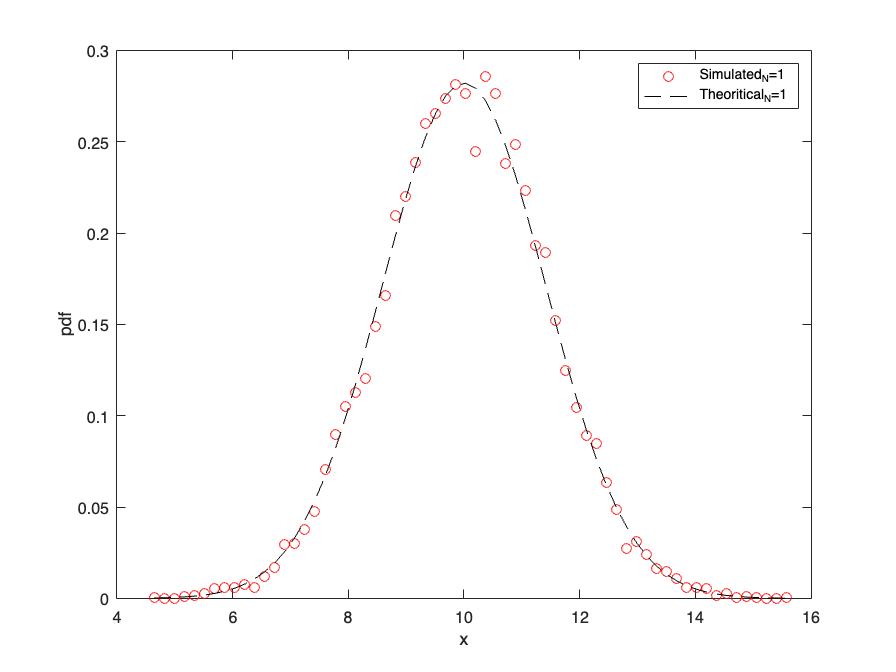


if abs(round(var(estimate),3) - round(CRLB_theta,3))== 0
    disp("The estimator is performing efficient")
end




[n1 x] = hist(estimate,64);
bin_width = x(2) - x(1);
theo_mean = theta;
CRLB = noise_var/ (N*(N+1)*((2*N)+1)/6);
theo_var = CRLB;
theo_pdf = 1 / (sqrt(2 * pi * theo_var)) * exp(-((x - theo_mean).^2) / (2 * theo_var));
plot(x,n1/(sum(n1)*(bin_width)),'ro',x,theo_pdf,'k--')
legend('Simulated_N=1','Theoritical_N=1');
xlabel('x');
ylabel('pdf')


hold on

N = 2

N = 2

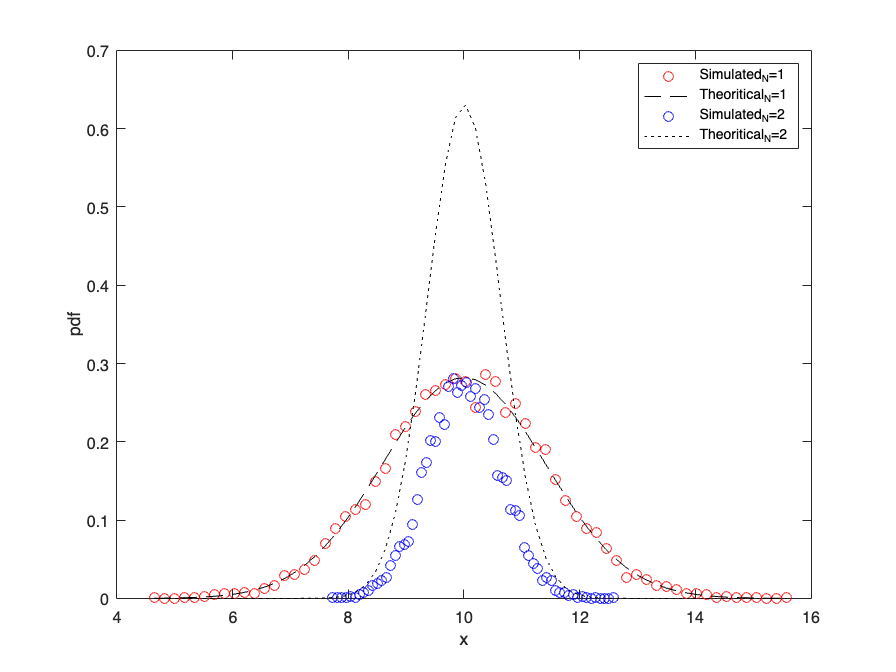

estimate1 = ones(1,numMonteCLoops)*NaN;

for MC=1:numMonteCLoops
    %%% defining the Numerator in the estimator equation
    % x[n]*n = theta*n*n + n*w[n]
    noisePart = randn(1,N)*sqrt(noise_var).*(1:N); % the WGN part
    numSignal = theta*(1:N).^2 + noisePart; % the signal parr

    %% defining the denominator in the estimator equation
    denomSignal = (1:N).^2;

    %% defining the estimate as the divisions of summations of numerator
    %% and denominator
    estimate1(MC) = sum(numSignal) / sum(denomSignal);    
end


[n2 x2] = hist(estimate1,64);
theo_var = noise_var/ (N*(N+1)*((2*N)+1)/6);
theo_pdf = 1 / (sqrt(2 * pi * theo_var)) * exp(-((x - theo_mean).^2) / (2 * theo_var));
plot(x2,n2/(sum(n2)*(bin_width)),'bo',x,theo_pdf,'k:')
legend('Simulated_N=1','Theoritical_N=1','Simulated_N=2','Theoritical_N=2');
xlabel('x');
ylabel('pdf')


hold on

N = 5

N = 5

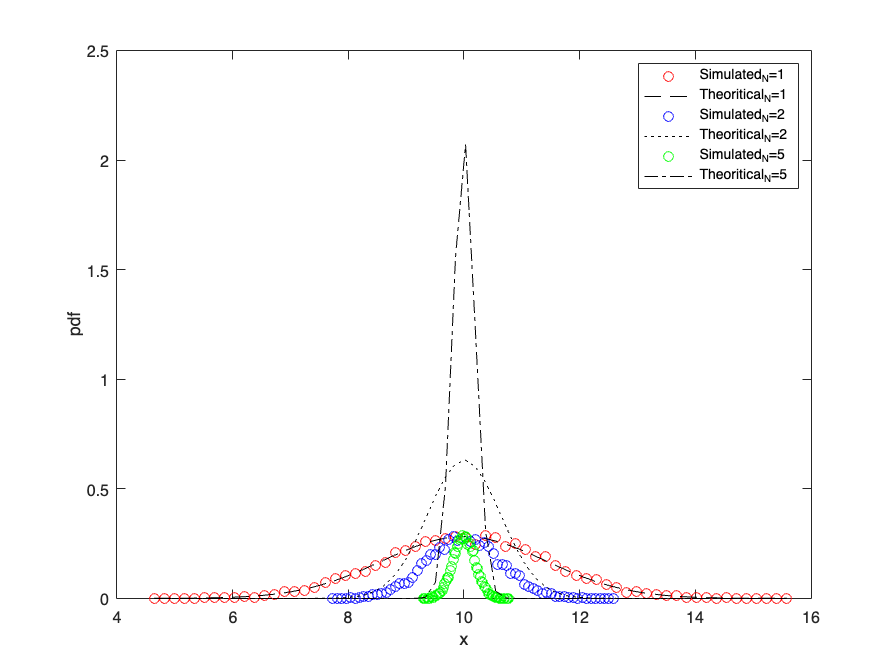

estimate1 = ones(1,numMonteCLoops)*NaN;

for MC=1:numMonteCLoops
    %%% defining the Numerator in the estimator equation
    % x[n]*n = theta*n*n + n*w[n]
    noisePart = randn(1,N)*sqrt(noise_var).*(1:N); % the WGN part
    numSignal = theta*(1:N).^2 + noisePart; % the signal parr

    %% defining the denominator in the estimator equation
    denomSignal = (1:N).^2;

    %% defining the estimate as the divisions of summations of numerator
    %% and denominator
    estimate1(MC) = sum(numSignal) / sum(denomSignal);    
end


[n2 x2] = hist(estimate1,64);
theo_var = noise_var/ (N*(N+1)*((2*N)+1)/6);
theo_pdf = 1 / (sqrt(2 * pi * theo_var)) * exp(-((x - theo_mean).^2) / (2 * theo_var));
plot(x2,n2/(sum(n2)*(bin_width)),'go',x,theo_pdf,'k-.')
legend('Simulated_N=1','Theoritical_N=1','Simulated_N=2','Theoritical_N=2','Simulated_N=5','Theoritical_N=5');
xlabel('x');
ylabel('pdf')


hold on

N = 10

N = 10

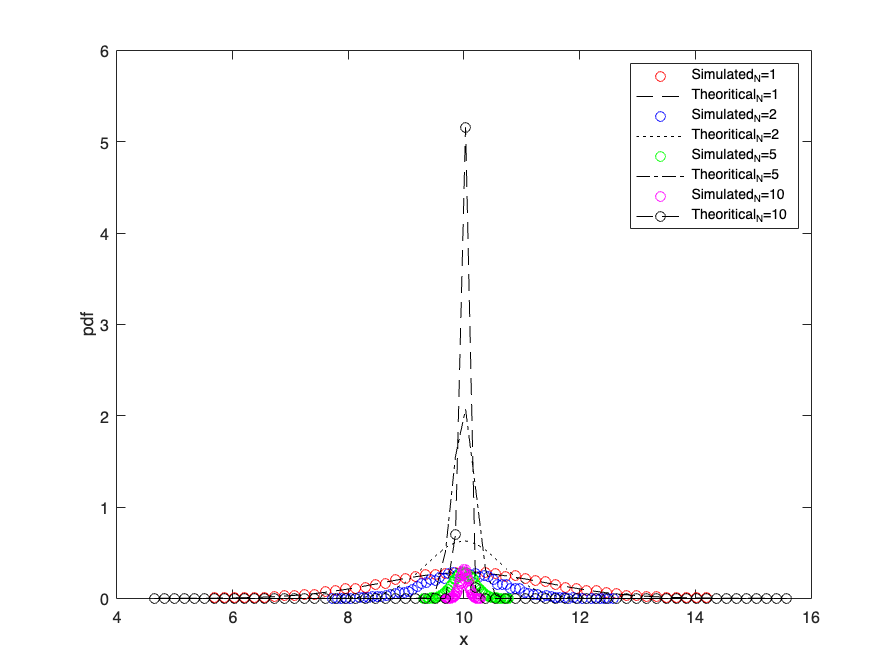

estimate1 = ones(1,numMonteCLoops)*NaN;

for MC=1:numMonteCLoops
    %%% defining the Numerator in the estimator equation
    % x[n]*n = theta*n*n + n*w[n]
    noisePart = randn(1,N)*sqrt(noise_var).*(1:N); % the WGN part
    numSignal = theta*(1:N).^2 + noisePart; % the signal parr

    %% defining the denominator in the estimator equation
    denomSignal = (1:N).^2;

    %% defining the estimate as the divisions of summations of numerator
    %% and denominator
    estimate1(MC) = sum(numSignal) / sum(denomSignal);    
end


[n2 x2] = hist(estimate1,64);
theo_var = noise_var/ (N*(N+1)*((2*N)+1)/6);
theo_pdf = 1 / (sqrt(2 * pi * theo_var)) * exp(-((x - theo_mean).^2) / (2 * theo_var));
plot(x2,n2/(sum(n2)*(bin_width)),'mo',x,theo_pdf,'ko--')

hold on
legend('Simulated_N=1','Theoritical_N=1','Simulated_N=2','Theoritical_N=2','Simulated_N=5','Theoritical_N=5','Simulated_N=10','Theoritical_N=10');
xlabel('x');
ylabel('pdf')